% explained: 
% https://docs.google.com/presentation/d/1druzobr5etF0IfLNmw6QOlxCoYYKbQ6Y/edit#slide=id.gd2be4d68d4_0_7

% parameters
apogee = 3393; %m
m=57.152; %kg
h = 250; %m set one layer as 250m
h_main = 250; %m when the main parachute is deployed
n = apogee/h; %layer
x0=0; %point of entry
y0=0;

%constants
g = 9.81; %m/s^2

%in the range of 165-230 degree in the early morning (avg 197.5)
%35-50 at noon @Cold lake mid August
wind_direction=(45)*ones(126,1);
curr_height = apogee;
counter=1;
x_total=0;
y_total=0;

%drogue air resistance
% parameters
% before the main parachute is deployed: drougue
diameter1=1.70434; %m ?
A=pi*(diameter1/2)^2; %m^2
Cd1=0.775; %

% after the main parachute is deployed: main parachute
diameter2=3.048; %m 120inches ?
A2=pi*(diameter2/2)^2;
Cd2=2.2; %

while(n>0)
    d = density_calculator(curr_height); %kg/m^3 density
    %T = temperature_calculator(curr_height);
    if (curr_height >= h_main)
        %t_layer: time it takes to travel through the current layer
        %v=sqrt(2mg/density*C(coefficient)*Area)
        v_terminal1=sqrt(2*m*g/(d*Cd1*A));
        t_layer=h/v_terminal1;
    else%curr_height < h_main
        
        v_terminal2=sqrt(2*m*g/(d*Cd2*A2));
        t_layer=h/v_terminal2;
    end
    %update the current height to one layer down
    curr_height=curr_height - h;
    wind_profile = magnitude_calculator(curr_height); %for checking function output
    wind_xcomponent=magnitude_calculator(curr_height)*sind(wind_direction(counter));
    wind_ycomponent=magnitude_calculator(curr_height)*cosd(wind_direction(counter));
    position_x = t_layer*wind_xcomponent; %distance by wind
    position_y = t_layer*wind_ycomponent;
    x_total=x_total+position_x;
    y_total=y_total+position_y;
    counter = counter + 1;
    n=n-1;
end
xposition_final=x0+x_total; %final x coordinate
yposition_final=y0+y_total; %final y coordinate
fprintf("average total distance:%f\n",(mean(xposition_final)^2+mean(yposition_final)^2)^0.5);

average total distance:865.654217


%fprintf("position_ydirection:%f\n",mean(yposition_final));
fprintf("terminal_velocity:%f",v_terminal2);

terminal_velocity:8.415512

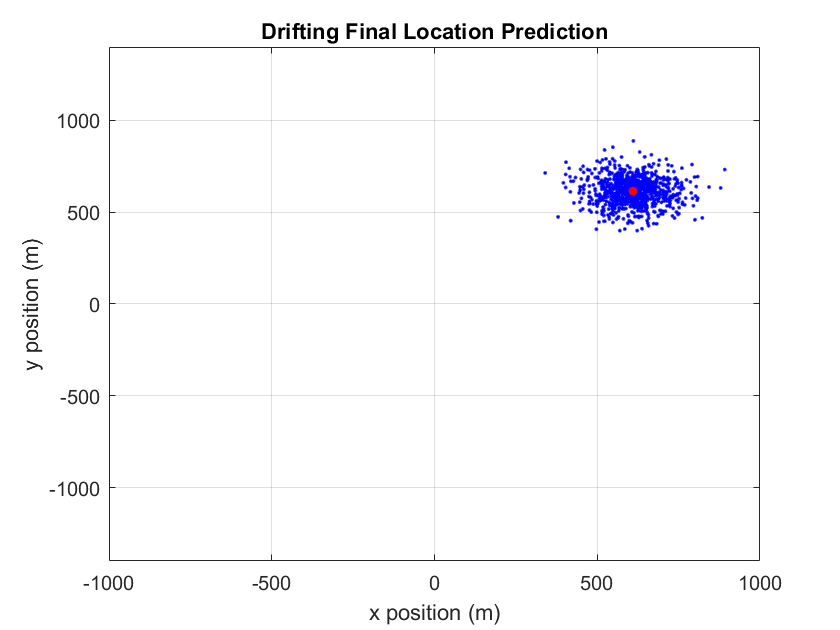


figure(1)
plot(xposition_final,yposition_final,"b.", "MarkerSize",5) 
hold on
plot(mean(xposition_final),mean(yposition_final),"r.", "MarkerSize",15)
hold off
grid on
axis([-1000 1000 -1400 1400])
xlabel('x position (m)')
ylabel('y position (m)')
title('Drifting Final Location Prediction')

function T = temperature_calculator(h) %unit: K, m
    if (h<11000) %gradient
        a = -0.0065; %a=6.5K/km
        T0=288.15; %K
        T = T0 + a*h;
    elseif (h<20000) %isothermal
        T = 216.66-273.15; %K
    end
end

% Air Density
function d = density_calculator(h)
        g0 = 9.80665; %m/s^2
        a = -0.0065; %6.5K/km
        R = 287; %J/(kg*K)
        T = temperature_calculator(h);
    if (h<11000) %gradient
        T1 = 288.15; %ground level temperature
        d = (T/T1)^(-(g0/(a*R)+1));
    elseif (h<20000)
        h1 = 11000; %m
        d = e^(-(g0/(R*T))*(h-h1));
    end

end

% Wind Magnitude
function vn = magnitude_calculator(x)
    varn = 1:0.01:10;  % Variance
    a = 37.55331224;
    b = 14.30107053;
    c = 6.7123204;
    v = a*exp((-(x/1000-b)^2) / (2*(c^2)));
    vn = v + sqrt(varn).*randn(size(varn)); % Signal + Noise
end
